# Gernuar U1L_20%_80% Transferfucntion Approx

clear;
load('U1L_20%_80%.mat','ch1_data','t_scope')

## Getting the correct start to calculate the function

First find out at what time the voltage starts to rise. Move the t_scope with that founded time.

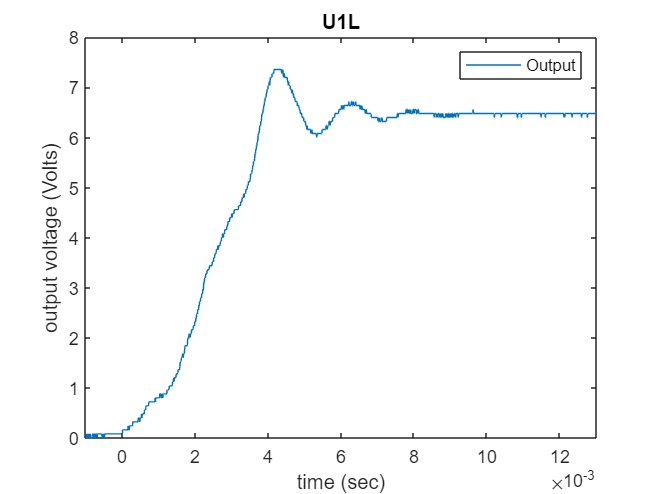

t_scope = t_scope(1:1500);
t_scope_2 = t_scope + 0.0108794;

ch1_data = ch1_data(1:1500);
Y1_data = ch1_data - ch1_data(1);

plot(t_scope_2,Y1_data)
title('U1L')
xlabel('time (sec)')
ylabel('output voltage (Volts)')
legend('Output')
xlim([-1e-3, 13e-3]);

## Creating a model from experimental Data

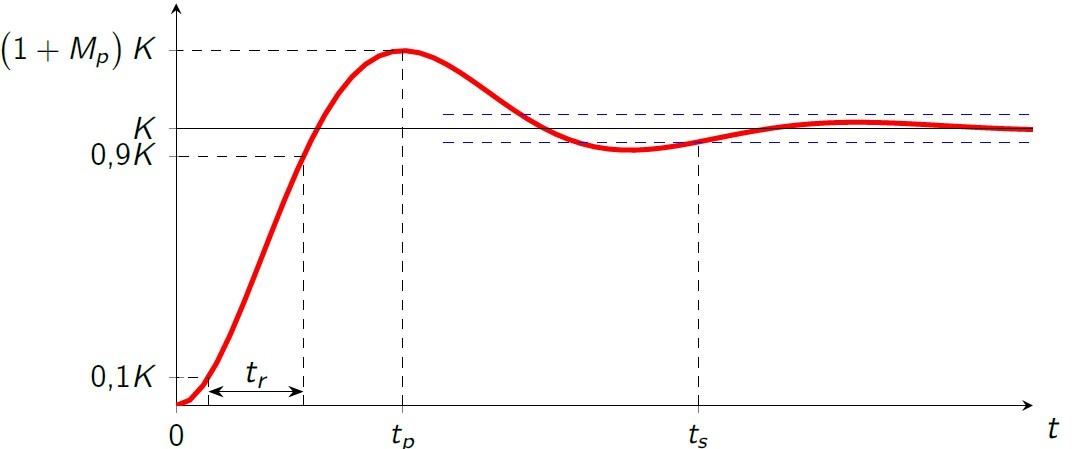


$$M_{\textrm{pt}} =\left(1+M_p \right)*K$$


$t_p =\frac{\pi }{\omega_d }$ = peaktime => $\omega_d =\frac{\pi }{t_p }$

$M_p =e^{-\pi *\frac{\sigma }{\omega_d }}$ = overschoot => $\sigma =\frac{\ln \left(M_p \right)}{-\pi }*\omega_d$


$$\omega_n =\sqrt{\sigma^2 +\omega_d^2 }$$


$\sigma =\zeta *\omega_{n\;}$=> $\zeta =\;\frac{\sigma }{\omega_n }$ = Dempingsfactor

step_data = stepinfo(Y1_data, t_scope_2)

step_data = struct with fields:
         RiseTime: 0.0030
    TransientTime: 0.0072
     SettlingTime: 0.0072
      SettlingMin: 5.8400
      SettlingMax: 7.3600
        Overshoot: 13.5802
       Undershoot: 0
             Peak: 7.3600
         PeakTime: 0.0042



W_d = (pi/step_data.PeakTime)

W_d = 754.8797

Sigma = -(log(step_data.Overshoot/100)*W_d)/pi

Sigma = 479.7433

W_n = sqrt(Sigma^2 + W_d^2)

W_n = 894.4255

DF = Sigma/W_n

DF = 0.5364


s = tf('s');
Ge =    (W_n^2/(s^2 +(2*DF*W_n)*s + W_n^2))

Ge =
 
          8e05
  --------------------
  s^2 + 959.5 s + 8e05
 
Continuous-time transfer function.



The fist calculated function is without the Gain (K). To get the Gain devide a point from the output with one of the calculated one, but it has to be with the same time value (t)

[y,t] = step(Ge, t_scope_2);

K = max(Y1_data)/max(y)

K = 6.4800


Ge_2 = K *(W_n^2/(s^2 +(2*DF*W_n)*s + W_n^2))

Ge_2 =
 
        5.184e06
  --------------------
  s^2 + 959.5 s + 8e05
 
Continuous-time transfer function.



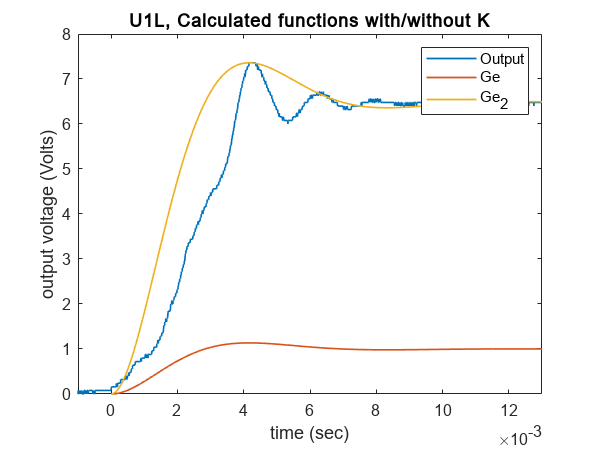


[f,x] = step(Ge_2, t_scope_2);
plot(t_scope_2, Y1_data,t,y, x, f,'LineWidth',1)
title('U1L, Calculated functions with/without K')
xlabel('time (sec)')
ylabel('output voltage (Volts)')
legend('Output', 'Ge' , 'Ge_2')
xlim([-1e-3, 13e-3]);
print -deps epsFig;

## Manual calculations by reading the graph

To verify if the calculated function is correct it was also calculated manually by reading the graph. The manually calculated answers will be inserted, so then the calculations can be done and verified. If you get about the same function and graph back, then you know its correct.

M_pt = 7.36;
k_bereken = 6.48;
M_p = (M_pt/k_bereken) - 1;
%t_p =  0.00416171;
t_p =   0.00440181;

Wd = (pi/t_p)

Wd = 713.7047

Sigm = -(log(M_p)*Wd)/pi

Sigm = 453.5757

Wn = sqrt(Sigm^2 + Wd^2)

Wn = 845.6390

DempF = Sigm/Wn

DempF = 0.5364


s = tf('s');
Ge_bereken = (Wn^2/(s^2 +(2*DempF*Wn)*s + Wn^2))

Ge_bereken =
 
          7.151e05
  ------------------------
  s^2 + 907.2 s + 7.151e05
 
Continuous-time transfer function.



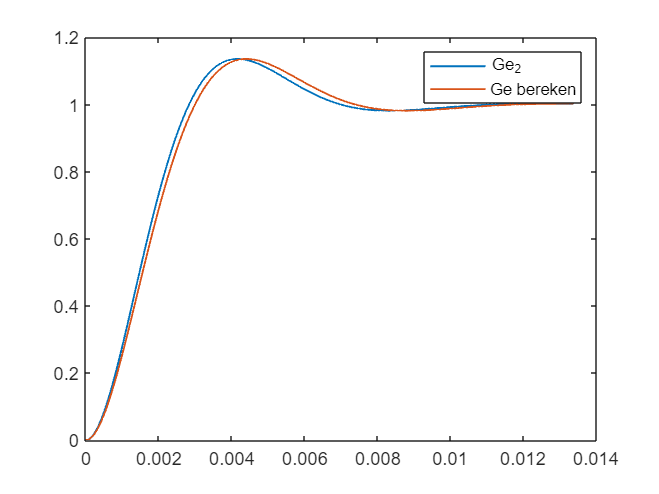


[f,x] = step(Ge_bereken, t_scope_2);
plot (t, y, x, f,'LineWidth',1)
legend('Ge_2','Ge bereken')